### MaxIter

- Wykresy poprawy

- Histogramy

- Tabela zestawieniowa

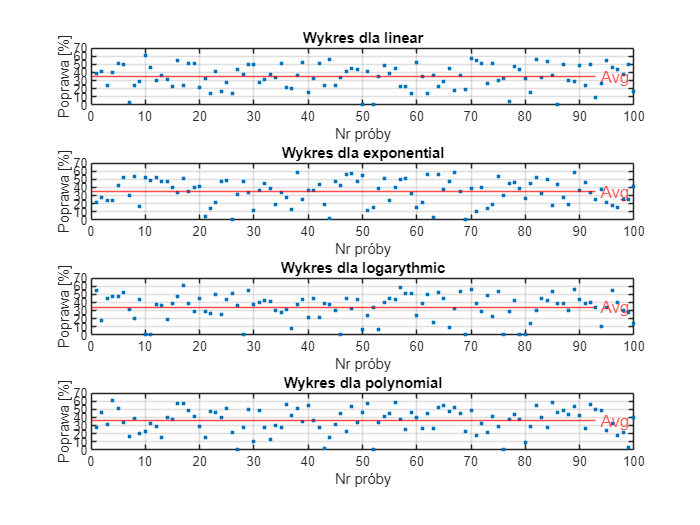

clear all; %#ok<CLALL>
load("results.mat")

linear_rel_imp = coolingScheduleData(coolingScheduleData.ExperimentName == "test_cooling_schedule_linear", {'RelativeImprovement'});
exponential_rel_imp = coolingScheduleData(coolingScheduleData.ExperimentName == "test_cooling_schedule_exponential", {'RelativeImprovement'});
logarythmic_rel_imp = coolingScheduleData(coolingScheduleData.ExperimentName == "test_cooling_schedule_logarithmic", {'RelativeImprovement'});
polynomial_rel_imp = coolingScheduleData(coolingScheduleData.ExperimentName == "test_cooling_schedule_polynomial", {'RelativeImprovement'});

linear_rel_imp.RelativeImprovement = linear_rel_imp.RelativeImprovement * 100;
exponential_rel_imp.RelativeImprovement = exponential_rel_imp.RelativeImprovement * 100;
logarythmic_rel_imp.RelativeImprovement = logarythmic_rel_imp.RelativeImprovement * 100;
polynomial_rel_imp.RelativeImprovement = polynomial_rel_imp.RelativeImprovement * 100;

linear_rel_imp_avg = mean(linear_rel_imp.RelativeImprovement);
exponential_rel_imp_avg = mean(exponential_rel_imp.RelativeImprovement);
logarythmic_rel_imp_avg = mean(logarythmic_rel_imp.RelativeImprovement);
polynomial_rel_imp_avg = mean(polynomial_rel_imp.RelativeImprovement);

linear_rel_imp_std = std(linear_rel_imp.RelativeImprovement);
exponential_rel_imp_std = std(exponential_rel_imp.RelativeImprovement);
logarythmic_rel_imp_std = std(logarythmic_rel_imp.RelativeImprovement);
polynomial_rel_imp_std = std(polynomial_rel_imp.RelativeImprovement);

cool_names = ["linear"; "exponential"; "logarythmic"; "polynomial";];
cool_avgs = [linear_rel_imp_avg; exponential_rel_imp_avg; logarythmic_rel_imp_avg; polynomial_rel_imp_avg];
cool_stds = [linear_rel_imp_std; exponential_rel_imp_std; logarythmic_rel_imp_std; polynomial_rel_imp_std];

cool_sched_comparison = table(cool_names, cool_avgs, cool_stds, 'VariableNames', {'cooling schedule', 'avg', 'std'});

max_value = max([max(linear_rel_imp.RelativeImprovement), ...
    max(exponential_rel_imp.RelativeImprovement), ...
    max(logarythmic_rel_imp.RelativeImprovement), ...
    max(polynomial_rel_imp.RelativeImprovement)]);
y_axis_limit_plot = ceil(max_value / 10) * 10;

bin_width = 5;
max_count_linear = max(histcounts(linear_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_exponential = max(histcounts(exponential_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_logarythmic = max(histcounts(logarythmic_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
max_count_polynomial = max(histcounts(polynomial_rel_imp.RelativeImprovement, 'BinWidth', bin_width));
y_axis_limit_hist = max([max_count_linear, max_count_exponential, max_count_logarythmic, max_count_polynomial]) + 10;

figure;

subplot(4, 1, 1);
plot(linear_rel_imp.RelativeImprovement, '.');
yline(linear_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla linear');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

subplot(4, 1, 2);
plot(exponential_rel_imp.RelativeImprovement, '.');
yline(exponential_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla exponential');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

subplot(4, 1, 3);
plot(logarythmic_rel_imp.RelativeImprovement, '.');
yline(logarythmic_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla logarythmic');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

subplot(4, 1, 4);
plot(polynomial_rel_imp.RelativeImprovement, '.');
yline(polynomial_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
title('Wykres dla polynomial');
xlabel('Nr próby');
ylabel('Poprawa [%]');
grid on;
ylim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_plot);

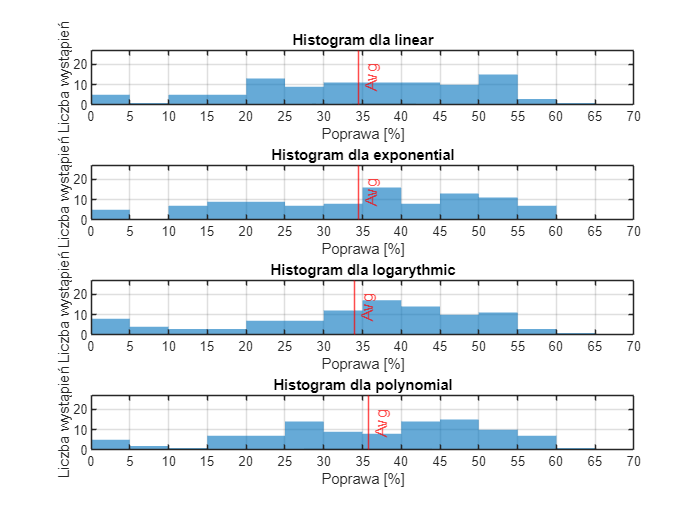


figure;

% Histogram dla linear_rel_imp
subplot(4, 1, 1);
histogram(linear_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(linear_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla linear');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);

% Histogram dla exponential_rel_imp
subplot(4, 1, 2);
histogram(exponential_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(exponential_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla exponential');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);

% Histogram dla logarythmic_rel_imp
subplot(4, 1, 3);
histogram(logarythmic_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(logarythmic_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla logarythmic');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);

subplot(4, 1, 4);
histogram(polynomial_rel_imp.RelativeImprovement, 'EdgeColor', 'none', 'BinWidth', bin_width);
hold on;
xline(polynomial_rel_imp_avg, 'Color', 'red', 'LineStyle', '-', 'Label', 'Avg', 'LabelVerticalAlignment', 'middle');
hold off;
title('Histogram dla polynomial');
xlabel('Poprawa [%]');
ylabel('Liczba wystąpień');
grid on;
ylim([0, y_axis_limit_hist]);
xlim([0, y_axis_limit_plot]);
yticks(0:10:y_axis_limit_hist);
xticks(0:bin_width:y_axis_limit_plot);


cool_sched_comparison

cool_sched_comparison = 4×3 table
    cooling schedule     avg       std  
    ________________    ______    ______

     "linear"            34.53    14.581
     "exponential"      34.495    15.218
     "logarythmic"      33.987    15.836
     "polynomial"       35.757    14.977
